data = load("../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt");

## Data loaded and now we define a function for conversion and apply it to

the data

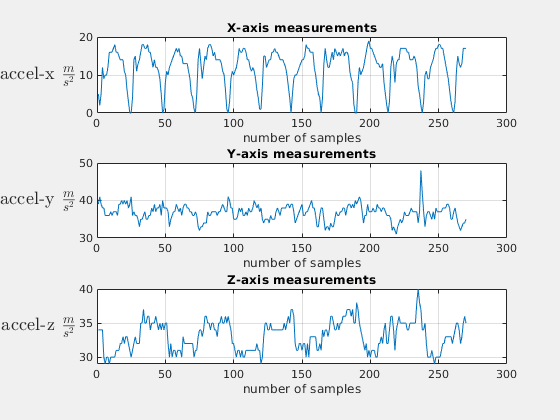

x = data(:,1);
y = data(:,2);
z = data(:,3);

plot_data(x,y,z,'Before conversion');

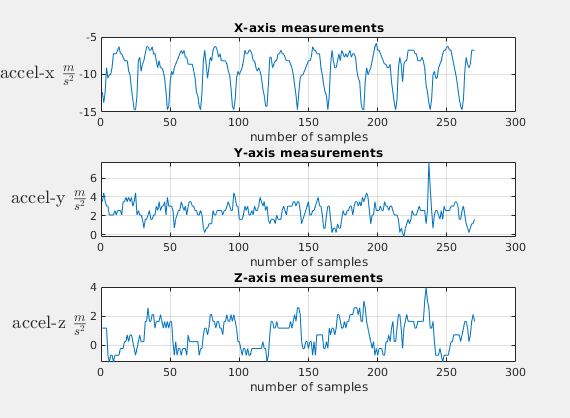


x = convert(data(:,1));
y = convert(data(:,2));
z = convert(data(:,3));

plot_data(x,y,z,'After conversion');

## Next is to set up the sampling 

need a cosine signal cos(2*pi*f*t) w/ f = 30Hz

run the code below and then view the 

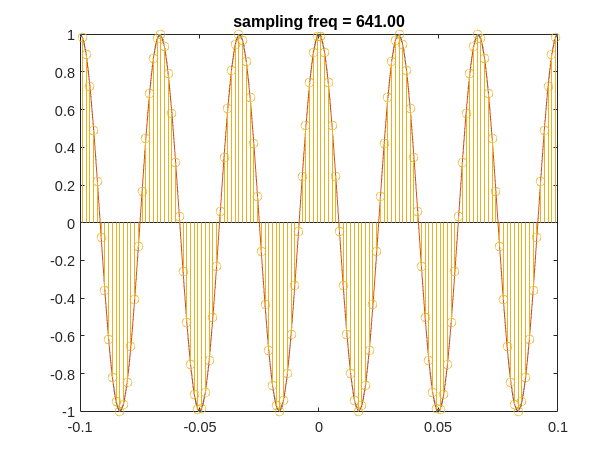

t = linspace(-0.5,0.5,1000);
c = (@(f,t) cos(2*pi*f*t));
Fs = 30;
figure
% sampling for 30,50,and 80 Hz
for i = 1:641
    plot(t,c(Fs,t)) % 30 Hz signal
    interval = linspace(-.5,.5,i+1); % interval samples
    f= [interval;c(Fs,interval)];
    hold on
    % sampled plot and stem
    plot(f(1,:),f(2,:))
    stem(f(1,:),f(2,:))
    title(sprintf("sampling freq = %.2f",i))
    xlim([-.1 .1])
    pause(.01)
    hold off
end

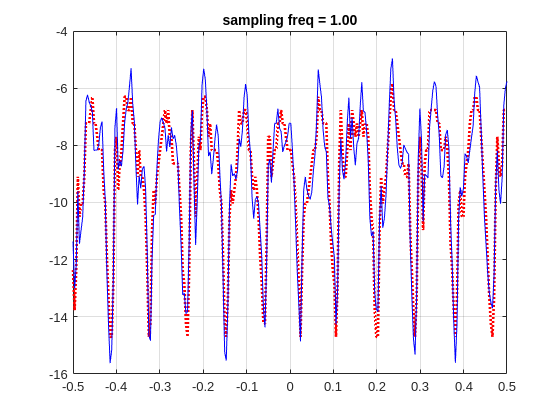

t = linspace(-0.5,0.5,length(x));

c = (@(f,t) cos(2*pi*f*t));
Fs = 30;
figure
% sampling for 30,50,and 80 Hz
for i = 1:32
    plot(t,x','r:',LineWidth=2)
    hold on
    plot(t,x'+c(Fs,t),'b-') % 30 Hz signal
    interval = linspace(-.5,.5,i+1); % interval samples
    f= [interval;c(32,interval)];
    % sampled plot and stem
    %plot(f(1,:),f(2,:))
    %stem(f(1,:),f(2,:))
    title(sprintf("sampling freq = %.2f",i))
    xlim([-.5 .5])
    grid on
    pause(.01)
    hold off
end

% from the MANUAL.txt file included in the data. 
figure
% example sampling freq of data we have
Fs = 32;
% the span of time/period gives the number of samples we have in the data.
% assuming we have N samples in the data, the span would be N*period
N =300;
t_span = N*(1/Fs);

t = 0:t_span/N:t_span;
% the frequencies we will test for the sampling
freq = .1:.1:64;
% their periods are 1/freq
Ts = freq.^(-1);

% the number of samples we would get in the range is then the floor of the
% span of time / period in the test sampling freq
n_s = floor(t_span./Ts)+1;
% 
% %plotting now every test freq we have in sample data
% for i = 1:1:length(freq)
%     % plotting the real signal
%     plot(t,2*cos(2*pi*t)-5*cos(3*pi/2 *t));
%     hold on;
%     % the sampled signal overlayed with the real one
%     t_s = 0:t_span/n_s(i):(t_span - 1/n_s(i));
%     plot(t_s, 2*cos(2*pi*t_s)-5*cos(3*pi/2 *t_s));
%     stem(t_s, 2*cos(2*pi*t_s)-5*cos(3*pi/2 *t_s));
%     title(sprintf("sampling freq = %.2f",freq(i)))
%     hold off;
%     pause(.01)
% end

figure
%plotting now every test freq we have in sample data
for i = 1:1:length(freq)
    % plotting the real signal
    plot(t,cos(2*pi*30*t));
    hold on;
    % the sampled signal overlayed with the real one
    t_s = 0:t_span/n_s(i):(t_span - 1/n_s(i));
    plot(t, cos(2*pi*freq(i)*t));
    stem(t, cos(2*pi*freq(i)*t));
    title(sprintf("sampling freq = %.2f",freq(i)))
    hold off;
    pause(.01)
end

n_s = floor(t_span./Ts)+1;
% example sampling freq of data we have
Fs = 32;
% the span of time/period gives the number of samples we have in the data.
N = length(x);
t_span = N*(1/Fs);
t = 0:t_span/N:(t_span-1/Fs);

freq = 2:1:640;
figure

%for i = [4 12 32 50 80]
for i = freq
    t_s = 0:t_span/n_s(i-1):(t_span - 1/n_s(i-1));
    
    abs_diff = abs(t(:) - t_s(:).');
    % Find the index of the minimum absolute difference for each element in vec2
    [~, closest_indices] = min(abs_diff, [], 1);

    plot(t,x,'k')    
    hold on 
    plot(t_s,x(closest_indices),'-*r')
    plot_title = sprintf('sampling freq = %.2f',i);
    title(plot_title)  
    xlim([0 5])
    hold off
    pause(.01)
end

according to the Readme in the repo, there is a defined max and min From the file: Acceleration data recorded in the dataset are coded according to the following mapping: [0; +63] = [-1.5g; +1.5g] the following function achieves this using the specified expression:

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end

% creates a plot with subregions for each of the three values of interest
% also includes a name for the figure to tell what set is plotted
function plot_data(x,y,z,name)
figure(Visible="on",Name=name)
subplot(3,1,1)
plot(1:length(x),x)
title 'X-axis measurements'
xlabel 'number of samples'
ylabel("accel-x $\frac{m}{s^2}$",Interpreter="latex",Rotation=0,FontSize=14)
grid on
subplot(3,1,2)
plot(1:length(y),y)
title 'Y-axis measurements'
xlabel 'number of samples'
ylabel("accel-y $\frac{m}{s^2}$",Interpreter="latex",Rotation=0,FontSize=14)
grid on
subplot(3,1,3)
plot(1:length(z),z)
title 'Z-axis measurements'
xlabel 'number of samples'
ylabel ("accel-z $\frac{m}{s^2}$",Interpreter="latex",Rotation=0,FontSize=14)
grid on

end